## SECTION 1a – Assessing sensor noise, accuracy, and signal to noise ratio (SNR)

### Load data file

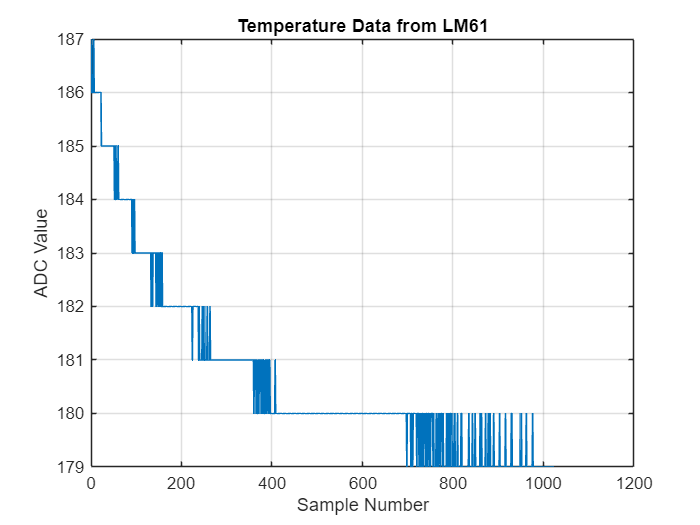

clear;  % Clear workspace
fname = "part1.mat";
load(fname);

% Plot raw pinch test data
figure
plot(outData(:, 1), outData(:, 2), 'LineWidth', 1)
grid('on');
title('Temperature Data from LM61')
xlabel('Sample Number');
ylabel('ADC Value');

### Estimate sensor noise

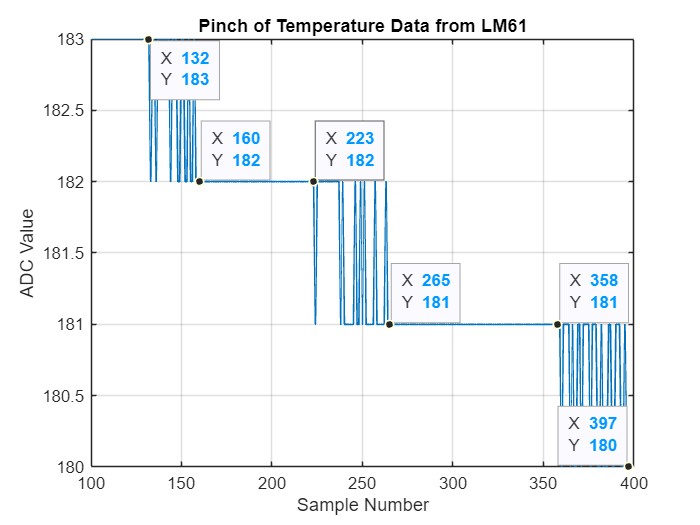

% Select a segment from your pinch data and create a new variable

% The first argument startSample:stopSample indicates the rows to choose.
% The second argument, just the colon indicates "give me all the columns".
startSample = 100;
stopSample = 400;
pinchSegment = outData(startSample:stopSample, :);

% Plot the data segment
figure
plot(pinchSegment(:, 1), pinchSegment(:, 2), 'LineWidth', 1)
grid('on');
title('Pinch of Temperature Data from LM61')
xlim([startSample, stopSample])  % Limit x-axis range to pinched sample values
xlabel('Sample Number');
ylabel('ADC Value');

% Code for datatips for measurements
ax = gca;
chart = ax.Children(1);
datatip(chart,397,180);
datatip(chart,358,181);
datatip(chart,160,182);
datatip(chart,132,183);
datatip(chart,265,181);
datatip(chart,223,182);

### Find the sensor noise

% Compute the sensor measurement noise standard deviation
% Find the distance averages (quantization magnitude, introduction slide 23)
d1 = 223 - 132;
d2 = 358 - 223;
distanceChatter = mean([d1 d2]);

% Find the average chatter width (introduction slide 24)
w1 = 160 - 132;
w2 = 265 - 223;
w3 = 397 - 358;
widthChatter = mean([w1 w2 w3]);

% Find the standard deviation of the samples (procedure page 9)
stdSamples = widthChatter / 6;

% Find the standard deviation of the sensor (procedure page 9)
sensorNoise = stdSamples / distanceChatter;

% Find the estimated total measurement noise (introduction slide 28)
% Add sensor noise in quadrature with quantization noise for 1 code value (0.29)
totalNoiseRawEst = sqrt(sensorNoise^2 + 0.29^2)

totalNoiseRawEst = 0.2949

### Check the estimate

To check this estimate we need to remove the temperature drift. The temperature drift adds to the value of the variance. From inspection, variance around drift due to quantization is much less than this. As was done in Lab 1 eliminate the contribution of drift by fitting a linear line to the data to estimate it.

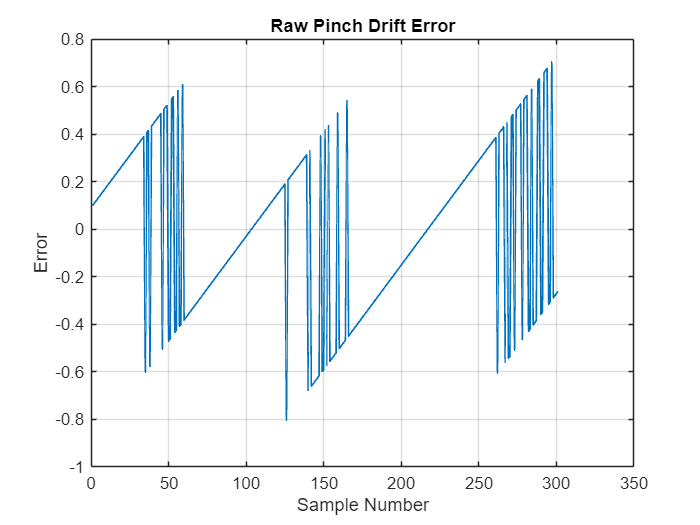

% Estimate the temperature drift of the signal by fitting a curve through
% your segment of data.

% Use the MATLAB polyfit command. You can try to use a linear fit (first
% order) or a quadratic fit (second order). This is an argument in the
% polyfit function
% coeffs = polyfit( xData, yData, order )
coeffs = polyfit(pinchSegment(:, 1), pinchSegment(:, 2), 1);
driftEstSlope = coeffs(1);
driftEstIntercept = coeffs(2);

% Create an estimate of the drift and find the error by removing the drift estimate
% from the pinch segment data
driftEstimate = driftEstSlope * pinchSegment(:, 1) + driftEstIntercept;
driftError = pinchSegment(:, 2) - driftEstimate;

% Plot the error
figure
plot(driftError, 'LineWidth', 1)
grid('on');
title('Raw Pinch Drift Error')
xlabel('Sample Number');
ylabel('Error');

% Compute the measured total noise
totalNoiseRaw = std(driftError)

totalNoiseRaw = 0.3436

## Section 1b - Oversample and Averaging to Reduce System Noise

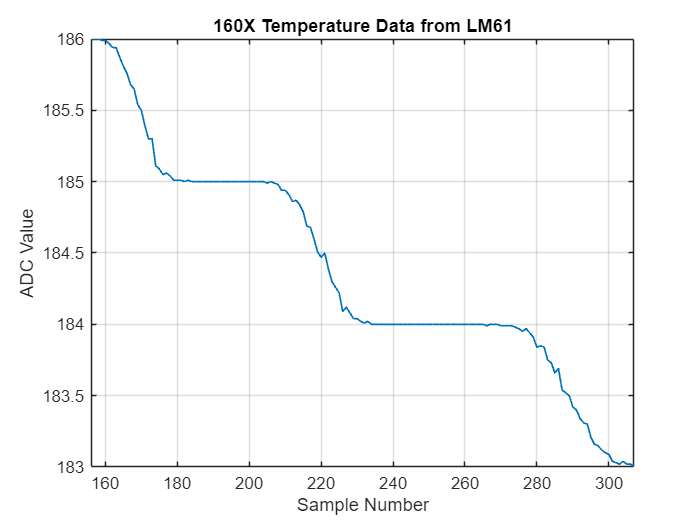

% Capture another set of pinch data using oversampling and save the data in a file.
% Load the file and plot the data
% Clear workspace, keep sensor noise, estimated raw noise, and measured raw
% noise
clearvars -except sensorNoise totalNoiseRawEst totalNoiseRaw;
fname = "part1b.mat";
load(fname);

% Plot OSA pinch test data
figure
plot(outData(:, 1), outData(:, 2), 'LineWidth', 1)
grid('on');
title('160X Temperature Data from LM61')
xlabel('Sample Number');
ylabel('ADC Value');

% Code for graph window resizing
xlim([156 307]);
ylim([183 186]);

% Find the estimated total measurement noise (introduction slide 28)
% Add sensor noise in quadrature with quantization noise for 1 code value (0.29)
totalNoiseOSAEst = sqrt(sensorNoise^2 + 0.29^2)

totalNoiseOSAEst = 0.2949

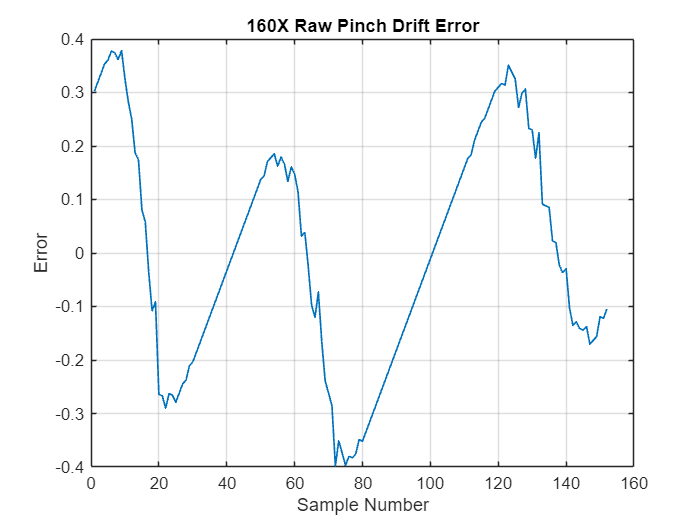

% Estimate the temperature drift of the signal by fitting a curve through
% a selected portion of the data.
pinchSegment = outData(156:307, :);

% Use the MATLAB polyfit command. You can try to use a linear fit (first
% order) or a quadratic fit (second order). This is an argument in the
% polyfit function
% coeffs = polyfit( xData, yData, order )
coeffs = polyfit(pinchSegment(:, 1), pinchSegment(:, 2), 1);
driftEstSlope = coeffs(1);
driftEstIntercept = coeffs(2);

% Create an estimate of the drift and find the error by removing the drift estimate
% from the pinch segment data
driftEstimate = driftEstSlope * pinchSegment(:, 1) + driftEstIntercept;
driftError = pinchSegment(:, 2) - driftEstimate;

% Plot the error
figure
plot(driftError, 'LineWidth', 1)
grid('on');
title('160X Raw Pinch Drift Error');
xlabel('Sample Number');
ylabel('Error');

% Compute the total noise when using oversampling and averaging (OSA)
totalNoiseOSA = std(driftError)

totalNoiseOSA = 0.2143

Oversampling by 160X did reduce the standard deviation of the error estimate but not by the amount it was expected to. The standard deviation of the error estimate should have come down by $\sqrt{N} = \sqrt{160}$ but it did not. This is because we are still getting a stair-stepping effect due to the same value being averaged over and over.

## Section 1c -  Adding Dithering Noise to Enable Oversampled Averaging

### Using testDAC() to test the hardware with ramp data

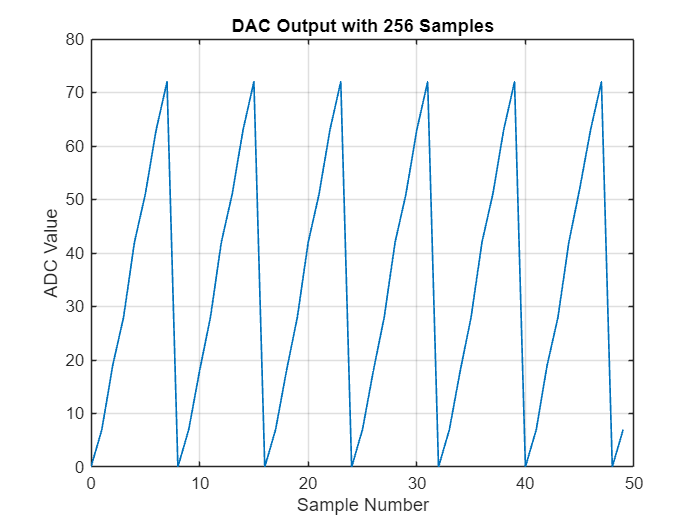

% Collect 256 samples of DAC voltage data, save the data, and then plot a
% representative subset using MATLAB
% Clear workspace, keep sensor noise, estimated raw noise, measured raw noise, estimated OSA noise, 
% and measured OSA noise
clearvars -except sensorNoise totalNoiseRawEst totalNoiseRaw totalNoiseOSAEst totalNoiseOSA;
fname = "part1c_4.mat";
load(fname);

% Create representative subset
subset = outData(1:50, :);

% Plot the subset of the DAC voltage data
figure
plot(subset(:, 1), subset(:, 2), 'LineWidth', 1)
grid('on');
title('DAC Output with 256 Samples')
xlabel('Sample Number');
ylabel('ADC Value');

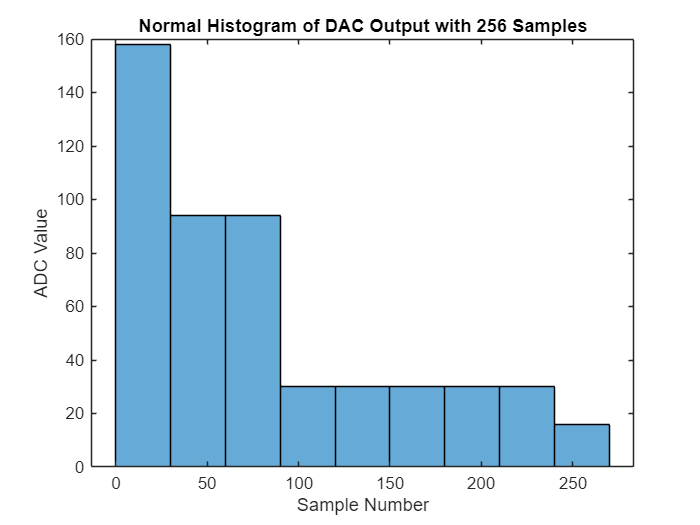

% Plot a normal histogram of the ramp data
figure
histogram(outData);
title('Normal Histogram of DAC Output with 256 Samples')
xlabel('Sample Number');
ylabel('ADC Value');

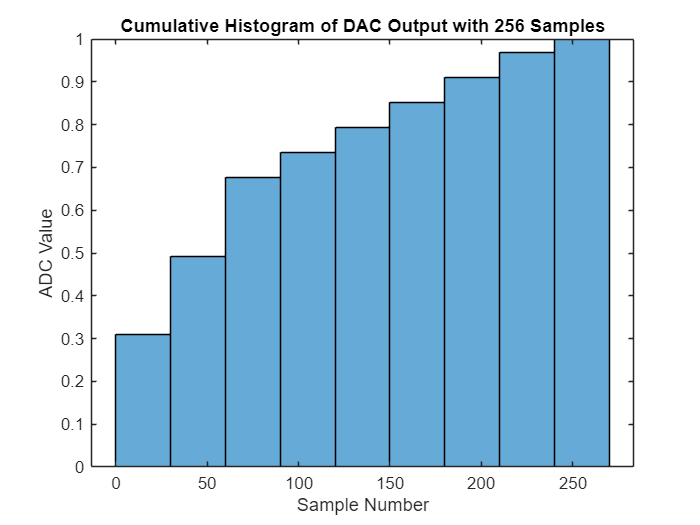

% Plot a cumulative histogram of the ramp data
figure
histogram(outData, 'Normalization', 'cdf');
title('Cumulative Histogram of DAC Output with 256 Samples')
xlabel('Sample Number');
ylabel('ADC Value');

% Compute the noise(standard deviation) of the ramp data
% To obtain readable values, we swapped the 47 ohm resistor for a 2.2k ohm
% resistor to scale the voltage up which also scales the std dev up.
% Therefore, we have to scale the std dev back down by the resistor ratio
% to use it in our calculations
ditherNoiseRamp = std(outData(:, 2)) * (50 / 2.2e3)

ditherNoiseRamp = 0.5576

### Using testDAC() to test the hardware with random data

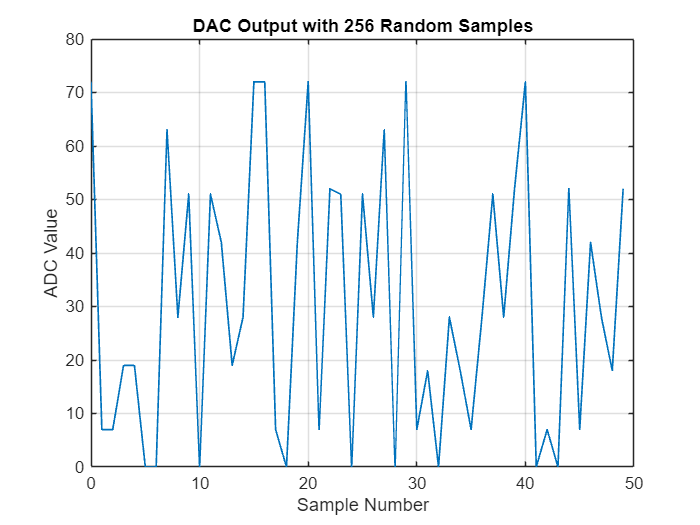

% Plot the data and histograms after changing the call parameter to testDAC() to random(256)
fname2 = "part1c_7.mat";
outData2 = importdata(fname2);

% Create same representative subset
subset2 = outData2(1:50, :);

% Plot the 256 random samples
figure
plot(subset2(:, 1), subset2(:, 2), 'LineWidth', 1)
grid('on');
title('DAC Output with 256 Random Samples')
xlabel('Sample Number');
ylabel('ADC Value');

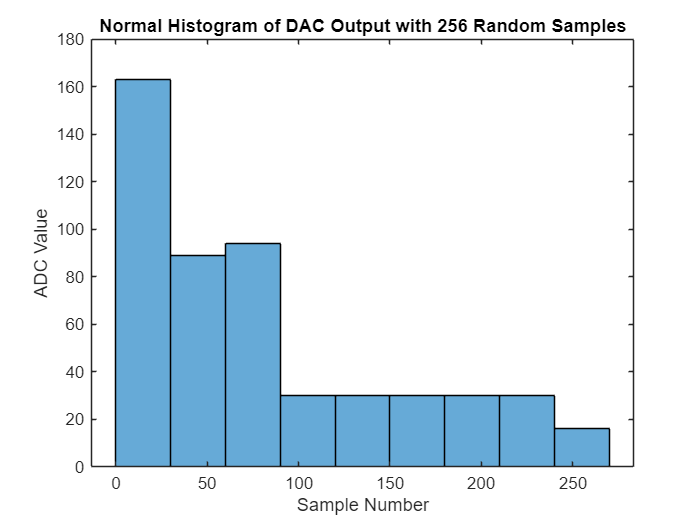

% Plot a normal histogram of the 256 random samples
figure
histogram(outData2);
title('Normal Histogram of DAC Output with 256 Random Samples')
xlabel('Sample Number');
ylabel('ADC Value');

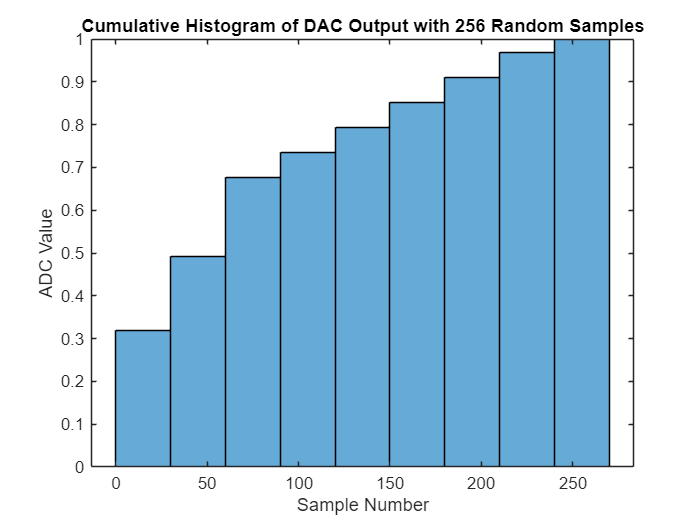

% Plot a cumulative histogram of the 256 random samples
figure
histogram(outData2, 'Normalization', 'cdf');
title('Cumulative Histogram of DAC Output with 256 Random Samples')
xlabel('Sample Number');
ylabel('ADC Value');

% Compute the noise(standard deviation) of the ramp data
% To obtain readable values, we swapped the 47 ohm resistor for a 2.2k ohm
% resistor to scale the voltage up which also scales the std dev up.
% Therefore, we have to scale the std dev back down by the resistor ratio
% to use it in our calculations
ditherNoiseRandom = std(outData2(:, 2)) * (50 / 2.2e3)

ditherNoiseRandom = 0.5778

## Section 1c - Dither Voltage Generator Hardware Description

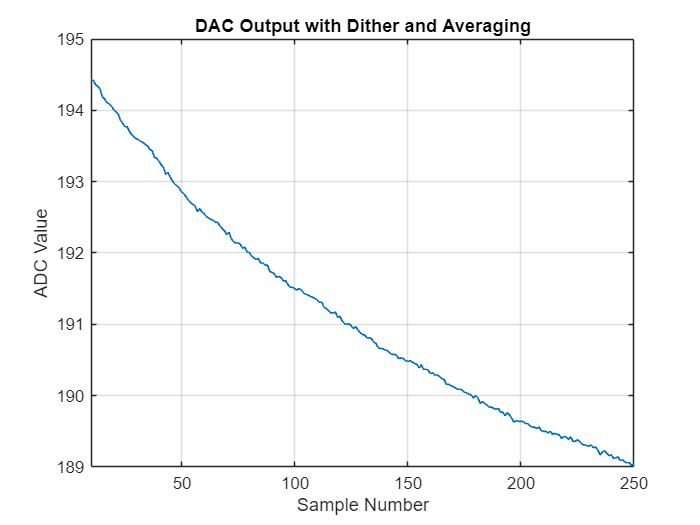

% Clear workspace, keep sensor noise, estimated raw noise, measured raw noise, estimated OSA noise, 
% measured OSA noise, measured ramp dither noise, and measured random dither noise
clearvars -except sensorNoise...
          totalNoiseRawEst totalNoiseRaw...
          totalNoiseOSAEst totalNoiseOSA...
          ditherNoiseRamp ditherNoiseRandom;

fname = "part1c_dither_4_attempt4.mat";
outData = importdata(fname);

% Plot the data taken with dither and averaging
figure
plot(outData(:, 1), outData(:, 2), 'LineWidth', 1)
grid('on');
title('DAC Output with Dither and Averaging')
xlabel('Sample Number');
xlim([10 250]);
ylabel('ADC Value');

% Find the estimated total measurement noise
% Add sensor noise in quadrature with dither noise and quantization noise for 1 code value (0.29)
totalNoiseDriftOSAEst = sqrt(sensorNoise^2 + ditherNoiseRandom^2 + (0.29)^2)

totalNoiseDriftOSAEst = 0.6488

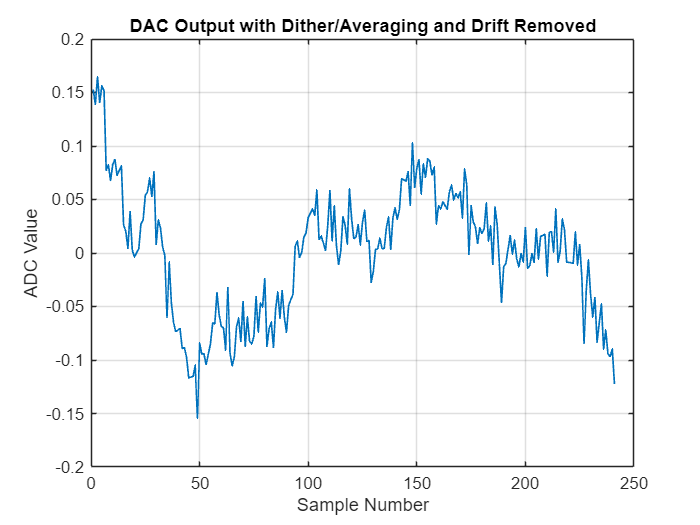

% Estimate the temperature drift of the signal by fitting a curve through
% a selected portion of the data.
selectedPortion = outData(10:250, :);
coeffs = polyfit(selectedPortion(:, 1), selectedPortion(:, 2), 2);
driftEstXSquared = coeffs(1);
driftEstX = coeffs(2);
driftEstNum = coeffs(3);

% Create an estimate of the drift and find the error by removing the drift estimate
% from the data
driftEstimate = (driftEstXSquared * selectedPortion(:, 1).^2) + (driftEstX * selectedPortion(:, 1)) + driftEstNum;
driftError = selectedPortion(:, 2) - driftEstimate;

% Plot the error
figure
plot(driftError, 'LineWidth', 1)
grid('on');
title('DAC Output with Dither/Averaging and Drift Removed')
xlabel('Sample Number');
ylabel('ADC Value');

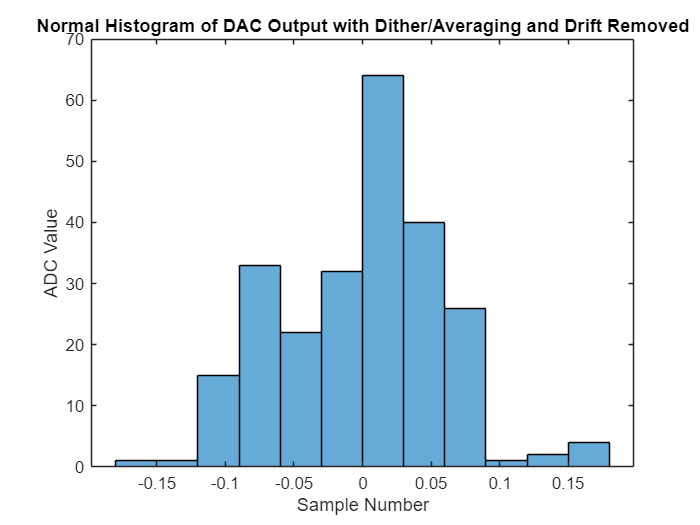

% Plot a PMF histogram of the error
figure
histogram(driftError);
title('Normal Histogram of DAC Output with Dither/Averaging and Drift Removed')
xlabel('Sample Number');
ylabel('ADC Value');

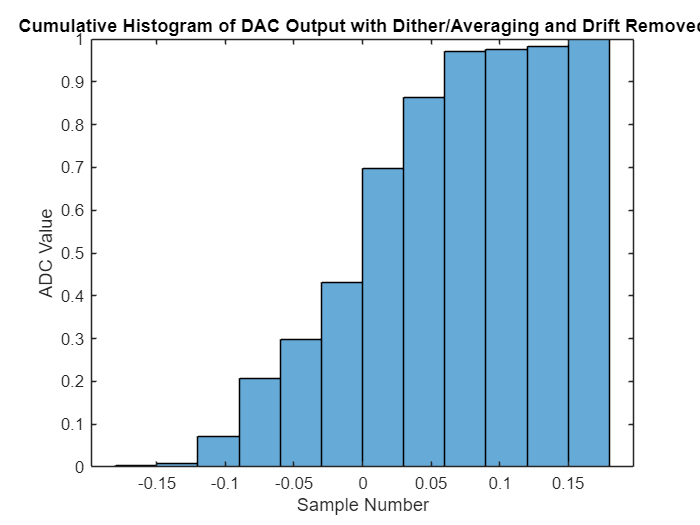

% Plot a CDF histogram of the error
figure
histogram(driftError, 'Normalization', 'cdf');
title('Cumulative Histogram of DAC Output with Dither/Averaging and Drift Removed')
xlabel('Sample Number');
ylabel('ADC Value');

% Compute the standard deviation of the error
totalNoiseDriftOSA = std(driftError)

totalNoiseDriftOSA = 0.0589

## Table 1

% Clear workspace, keep sensor noise, estimated raw noise, measured raw noise, estimated OSA noise, 
% measured OSA noise, measured ramp dither noise, measured random dither noise, estimated dither OSA noise, 
% and measured dither OSA noise
clearvars -except sensorNoise...
                  totalNoiseRawEst totalNoiseRaw...
                  totalNoiseOSAEst totalNoiseOSA...
                  ditherNoiseRamp ditherNoiseRandom...
                  totalNoiseDriftOSAEst totalNoiseDriftOSA;

### Create Table 1

quantities = ["1 Code Value Signal";...
              "Sensor Noise SD";...
              "Quant Noise SD";...
              "Dither Noise SD";...
              "Total Input Noise";...
              "Noise after averaging (theoretical)";...
              "Noise after averaging (measured)"];
rawValues         = [1.00; 0.00; 0.29; 0.00; 0.00; 0.00; 0.00];
valuesNoDither    = [1.00; 0.00; 0.29; 0.00; 0.00; 0.00; 0.00];
valuesNoDitherAvg = [1.00; 0.00; 0.29; 0.00; 0.00; 0.00; 0.00];
varNames = ["Quantity",...
            "Raw Values (No Averaging)",...
            "Values after 160x Oversampling and Averaging (No Dithering)",...
            "Values after 160x Oversampling and Averaging(with Dithering)"];
table1 = table(quantities, rawValues, valuesNoDither, valuesNoDitherAvg, 'VariableNames', varNames);

### Compute values for Table 1

% Global values
oneCV = 1.00;
quantNoise = 0.29;
nSamples = 160;

% Raw Values (No Averaging)
% sensorNoise from section 1a
% totalNoiseRawEst from section 1a
% totalNoiseRaw from section 1a
% No "noise after averaging" estimation because no averaging, so the
% estimated and average estimated values are the same
table1{:, "Raw Values (No Averaging)"} = [oneCV; sensorNoise; quantNoise; 0.00; totalNoiseRawEst; totalNoiseRawEst; totalNoiseRaw];

% OSA only case
% sensorNoise from section 1a
% totalNoiseOSAEst from section 1b
% totalNoiseOSA from section 1b
% Estimation of averaged input noise (typical error)
totalNoiseOSAEstAvg = totalNoiseOSAEst / sqrt(nSamples);
table1{:, "Values after 160x Oversampling and Averaging (No Dithering)"} = [oneCV; sensorNoise; quantNoise; 0.00; totalNoiseOSAEst; totalNoiseOSAEstAvg; totalNoiseOSA];

% Dither and OSA case
% sensorNoise from section 1a
% totalNoiseDriftOSAEst from section 1c
% totalNoiseDriftOSA from section 1c
% Estimation of averaged input noise (typical error)
totalNoiseDriftOSAEstAvg = totalNoiseDriftOSAEst / sqrt(nSamples);
table1{:, "Values after 160x Oversampling and Averaging(with Dithering)"} = [oneCV; sensorNoise; quantNoise; ditherNoiseRamp; totalNoiseDriftOSAEst; totalNoiseDriftOSAEstAvg; totalNoiseDriftOSA];

% Display table 1
table1

table1 = 7×4 table
                  Quantity                   Raw Values (No Averaging)    Values after 160x Oversampling and Averaging (No Dithering)    Values after 160x Oversampling and Averaging(with Dithering)
    _____________________________________    _________________________    ___________________________________________________________    ____________________________________________________________

    "1 Code Value Signal"                                   1                                             1                                                               1                          
    "Sensor Noise SD"                                0.053589                                      0.053589                                                        0.053589                          
    "Quant Noise SD"                                

## SECTION 1d – Effective ADC Bit Depth from Dithering Noise and Averaging

% Compute the increase in the effective resolution (in bits) of the ADC by using dithering and averaging
% Find the increase by taking the total dither OSA noise and treating it as
% the new quantization noise, then divide the new noise by the old


$$$\frac{\sigma_{dithOSA}}{\sigma_{quant}} = 2^n$$$
     
$$$n = \log_2(\frac{\sigma_{quant}}{\sigma_{dithOSA}})$$


increase = quantNoise / totalNoiseDriftOSA;
addedBits = log2(increase)

addedBits = 2.2986

The microcontroller used is the ATMega328P, which has a 10-bit ADC. This means that the new system has performance better than a 12-bit system, but not as good as a 13-bit system.

## Section 2 - Precision and Accuracy Calculation in Engineering Units

"The output voltage of the LM61 is linearly proportional to temperature (10 mV/°C) and has a DC offset of 600 mV. The offset allows reading negative temperatures without the need for a negative supply." (Page 1, Description)

source: [https://www.ti.com/lit/ds/symlink/lm61.pdf?ts=1728062559449&ref_url=https%253A%252F%252Fwww.google.com%252F](https://www.ti.com/lit/ds/symlink/lm61.pdf?ts=1728062559449&ref_url=https%253A%252F%252Fwww.google.com%252F)


$$$V_o = (10\frac{mV}{\degree{C}} * T\degree{C}) + 600mV$$$
      
$$$\Rightarrow$$$
      
$$$T\degree{C} = \frac{V_o - 600mV}{10\frac{mV}{\degree{C}}}$$$


"For single ended conversion, the result is:" (Page 215, 23.7)

source: [https://ww1.microchip.com/downloads/en/DeviceDoc/Atmel-7810-Automotive-Microcontrollers-ATmega328P_Datasheet.pdf](https://ww1.microchip.com/downloads/en/DeviceDoc/Atmel-7810-Automotive-Microcontrollers-ATmega328P_Datasheet.pdf) 


$$$ADC = \frac{v_{in} * 1024}{V_{REF}}$$$
      
$$$\Rightarrow$$$
      
$$$V_{IN} = \frac{ADC * V_{REF}}{1024}$$$


% Plot the temperature in the three measurement units: ADC value, voltage,
% and temperature in degC
